## Tutorial 5: Two step optimization part two: the cell refinement module

In this tutorial, we will discuss the first important step of optimizing EXTRACT's hyperparameters: the cell finding module. For this tutorial, we use a published two-photon calcium imaging movie, which is courtesy of Ben Yang -Parker Lab. See Parker, J.G., Marshall, J.D., Ahanonu, B. et al. Diametric neural ensemble dynamics in parkinsonian and dyskinetic states. Nature 557, 177–182 (2018). https://doi.org/10.1038/s41586-018-0090-6 Extended Data Fig 4 for more information.

### Hyperparameter tuning flag

Within EXTRACT, we have a flag for optimizing the cell refinement module (config.hyperparameter_tuning_flag). When this parameter is true, EXTRACT performs a single cell refinement step and saves the quality metrics. The function, plot_hyperparameter_curves.m, can then be used to plot the quality metrics. These plots are then starting points for the tuning of the quality metric thresholds. 

M = 'jones.h5:/data';
config = get_defaults([]);
config.downsample_time_by = 4;
config.spatial_lowpass_cutoff = 1;
config.use_gpu = 0;
config.hyperparameter_tuning_flag = 1;
config.cellfind_min_snr = 0;
config.thresholds.T_min_snr = 3.5;
config.cellfind_min_snr = 0;
config.adaptive_kappa = 2;
output = extractor(M,config);

06-Jul-2024 19:40:09: Signal extraction will run on 1 partitions serially... 
06-Jul-2024 19:40:09: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.1 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.0761 
	 	 	 	 minimum magnitude: 0.0287 
			 Step #100, found 98 cells... 
			 Step #200, found 167 cells... 
	 	 	 177 cells found after a total of 235 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 S-step # 1: 177 cells (npx:4, npy:4)
	 	 	 Terminating the cell-refinement for hyperparameter tuning 
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 177 cells.
06-Jul-2024 19:41:09: Total of 177 cells are found.
06-Jul-2024 19:41:09: Removing duplicate cells...
06-Jul-2024 19:41:09: 177 cells were retained after removing duplicates.
06-Jul-2024 19:41:09: All done with EXTRACT! 


plot_hyperparameter_curves(output)

### Final run with configured parameters

There are several important information from these plots we can use to pick some of the parameters. 

- Firstly, the data points in the T_min_snr curve still seems to be too close to the threshold. We might wish to lower it further (here down to 3.2). 

- Next, the spatial corruption values are at ~ 4-5 values, much higher than the default value of 1.5. This is expected for very noisy movies. We need to increase this threshold value if we wish to keep the cells (here to 5). 

- Next, the extracted cell arease seem to be rather small, usually a sign that either our average cell radius is quite off or that kappa_std_ratio is too strict. We change the latter to 1 here. 

- Finally, we observe a long tail in the T_dup_corr threshold curves, which is why we set the correlation threshold to 0.8. We finetuned this value while checking the final outputs for a few runs and ensuring that duplicate cells are properly discarded.

M = 'jones.h5:/data';
config = get_defaults([]);
config.downsample_time_by = 4;
config.spatial_lowpass_cutoff = 1;
config.use_gpu = 0;
config.max_iter = 10;
config.cellfind_min_snr = 0;
config.thresholds.T_min_snr = 3.2;
config.thresholds.spatial_corrupt_thresh = 5;
config.thresholds.T_dup_corr_thresh = 0.8;
config.adaptive_kappa = 2;
config.kappa_std_ratio = 1;
output = extractor(M,config);

06-Jul-2024 20:01:34: Signal extraction will run on 1 partitions serially... 
06-Jul-2024 20:01:34: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.1 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.0761 
	 	 	 	 minimum magnitude: 0.0287 
			 Step #100, found 99 cells... 
			 Step #200, found 173 cells... 
			 Step #300, found 218 cells... 
	 	 	 232 cells found after a total of 351 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 207 (25 removed) 
	 	 	 End of iter # 2: # cells: 174 (33 removed) 
	 	 	 End of iter # 3: # cells: 164 (10 removed) 
	 	 	 End of iter # 4: # cells: 157 (7 removed) 
	 	 	 End of iter # 5: # cells: 151 (6 removed) 
	 	 	 End of iter # 6: # cells: 146 (5 removed) 
	 	 	 End of iter # 7: # cells: 146 (0 removed) 
	 	 	 End of iter # 8: # cells: 141 (5 removed) 
	 	 	 End of iter # 9: # cells: 141 (0 

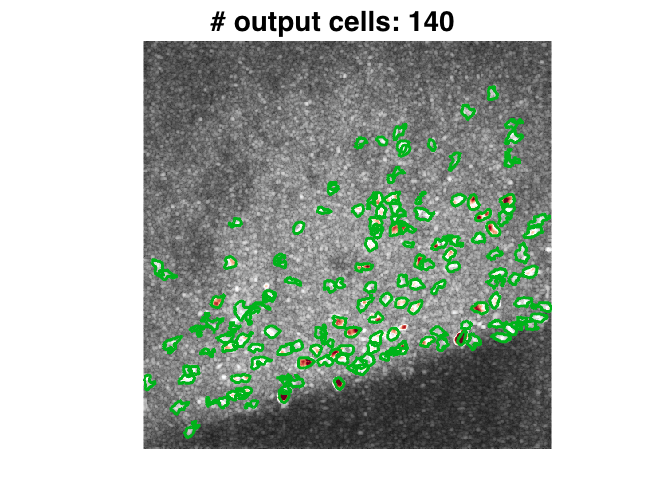

figure
plot_output_cellmap(output,[],[],'clim_scale',[0, 0.999])

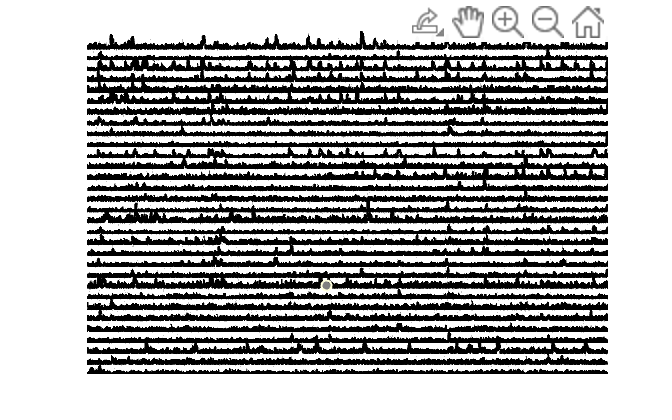

figure
T_ex = output.temporal_weights';
plot_stacked_traces_double(T_ex(1:31,:),[],0)

With that, we were able to optimize the cell refinement module as well. We picked the number of iterations to be 10, which was empirically when the cell profiles stabilized (you can check this by setting config.visualize_cellfinding = 1). Moreover, we kept the adaptive estimation for cell refinement (adaptive_kappa = 2), which was particularly helpful for this low SNR movie.